# Battery Management System Controller HIL Testing

## Description

This reference example showcases model-in-the-loop (MIL) and hardware-in-the-loop (HIL) testing of Battery Management Systems (BMS). The plant consists of a 48V battery system composed of 12 cells connected in series. The battery system is emulated in real-time using the Speedgoat [Battery Cell Emulator](https://www.speedgoat.com/products/battery-management-systems-battery-cell-emulator).

## Learn how to:

- Model a 48V battery system using [Simscape™ Battery™](https://ch.mathworks.com/products/simscape-battery.html).

- Go from model-in-the-loop MIL to HIL without leaving [Simulink®](https://ch.mathworks.com/products/simulink.html) or changing your model.

- Interface your [Simulink®](https://ch.mathworks.com/products/simulink.html) / [Simscape™ Battery™](https://ch.mathworks.com/products/simscape-battery.html) models with battery cell emulation hardware.

- Validate BMS functions, such as fault detection, cell balancing, and State of Charge (SoC) estimation.

- Implement bus and signal-level communication with the BMS controller.

- Simulate temperature sensors and implement fault conditions.

## **Supported Model-based Design Use Cases **

This example supports the following simulation modes (see image below):

- Desktop MIL: Both the battery plant and BMS controller run on the development computer. Use this simulation mode to test and verify the BMS logic in closed-loop desktop simulation.

- Real-time MIL: Both the battery plant and BMS controller run in real-time on the Speedgoat HIL test system to validate real-time aspects. The development computer is used to control the simulation, fine-tune battery plant and BMS controller parameters, and measure and record real-time data.

- HIL: Reuse existing controller model to generate code onto general purpose automotive microcontroller, acting as Battery Management Unit (BMU). Extend the BMU with a Cell Monitoring Unit (CMU) and the HIL testbench with battery cell emulation hardware. Validate BMS functions by interfacing the BMS (BMU + CMU) controller against the battery digital twin running on Speedgoat hardware. Conduct both interactive and automated HIL testing.

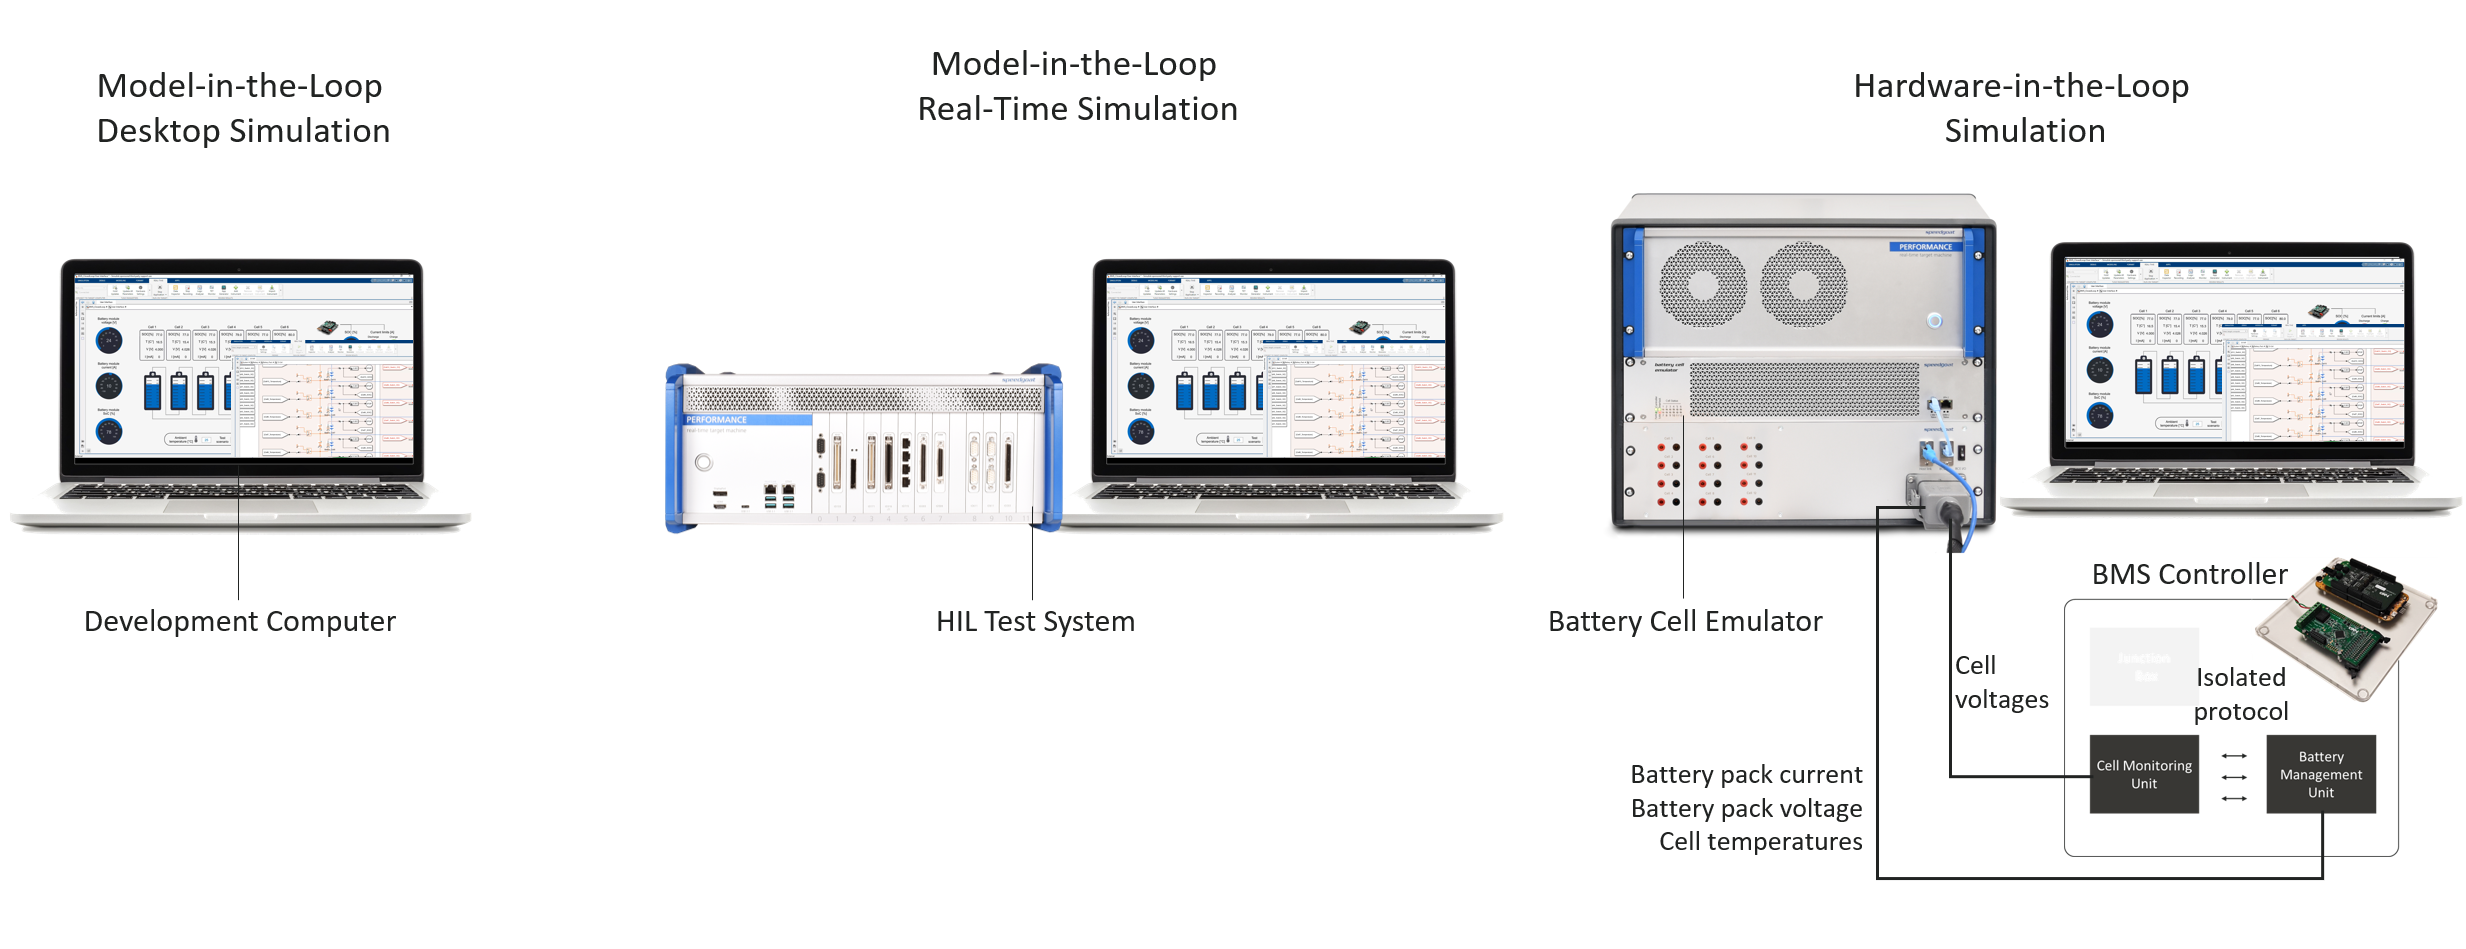

## System Requirements

###     MathWorks®** Products**

- [Simulink® Real-Time™](https://ch.mathworks.com/products/simulink-real-time.html?s_tid=srchtitle) - [product requirements](https://www.mathworks.com/support/requirements/simulink-real-time.html)

- [Simscape™ Battery™](https://ch.mathworks.com/products/simscape-battery.html)

###    ** Speedgoat Products**

- [Performance Real-Time Target Machine](https://www.speedgoat.com/products-services/real-time-target-machines/performance-real-time-target-machine)                        

- [IO611 CAN FD I/O Module](https://www.speedgoat.com/products/communication-protocols-can-fd-io611)

- [Battery Cell Emulator](https://www.speedgoat.com/products/battery-management-systems-battery-cell-emulator)

###     Third-Party Products

- [NXP Evaluation Board for Automotive General Purpose (S32K144-Q100)](https://www.nxp.com/design/development-boards/automotive-development-platforms/s32k-mcu-platforms/s32k144-q100-evaluation-board-for-automotive-general-purpose:S32K144EVB)

- [NPX Isolated Network High-Speed Transceiver (MC33664ATL)](https://www.nxp.com/design/software/analog-expert-software-and-tools/sdk-analog-expert-drivers/evaluation-board-for-mc33664atl-isolated-network-high-speed-transceiver:FRDMDUAL33664EVB?van=tidFRDMDUAL33664EVB)

- [NXP Cell Monitoring Unit (MC33771)](https://www.nxp.com/products/power-management/battery-management/battery-cell-controllers/evaluation-board-for-mc33771-with-isolated-daisy-chain-communication:FRDM33771BTPLEVB)

- [NXP Support Package S32K1xx](https://ch.mathworks.com/matlabcentral/fileexchange/64740-nxp-support-package-s32k1xx)

## HIL Testbench Configuration 

### Generate Code and Deploy Controller Logic to BMS Controller

This section instructs how to generate code and run the BMS controller logic on the [NXP Evaluation Board for Automotive General Purpose (S32K144-Q100)](https://www.nxp.com/design/development-boards/automotive-development-platforms/s32k-mcu-platforms/s32k144-q100-evaluation-board-for-automotive-general-purpose:S32K144EVB).

% Open model containing controller logic for F28379D target hardware
mdl = 'Controller_HIL.slx';
open_system(mdl);

% Connect target hardware to host computer (USB)

% Build and Deploy Code to target hardware
slbuild(mdl);

### Connect BMS Controller to HIL Test System 

BMS Controller (consisting of a BMU and a CMU) and the Speedgoat HIL test system should be connected according to the pin mapping outlined in the table below.

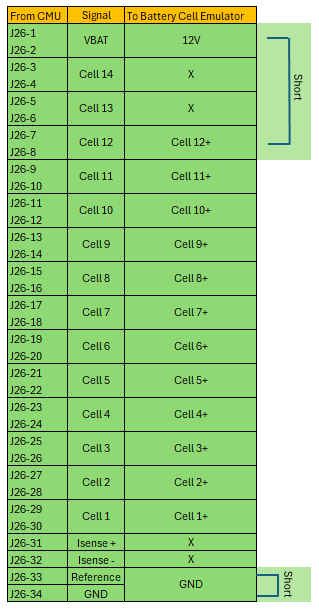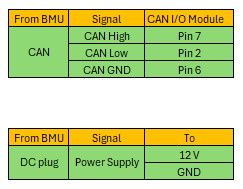

It is important to short VBAT and Cell 12 as the NXP Cell Monitoring Unit contains 14 cells and we only use 12 cells for this reference example. 'Reference' and 'GND' should also be shorted internally. The pins marked with 'X' can be left disconnected.

### Generate Battery Module

run BuildPackwFaults.m

The above command will generate a battery module with 12 parallel assemblies with 1 cell each. It is also generated with a configuration to balance each parallel assembly externally.

## Exercises

The following exercises are primarily documented for HIL simulation mode. For users who do not have access to the specified BMS controller setup, we recommend performing these exercises using desktop or real-time MIL simulation mode.

### A. BMS Interactive Testing using Simulink Dashboard

#### A1. Run Testbench in HIL Simulation Mode

This section provides instructions on how to use [Simulink®](https://ch.mathworks.com/products/simulink.html) to conduct interactive BMS HIL testing.

mdl = 'SystemModel';
open_system(mdl);

% Configure testbench for HIL simulation using detailed model
switchConfig("HIL");

% Build the Simulink model
slbuild(mdl);

% Assign Realtime object to a variable
tg = slrealtime;

% Download and install the real-time application on the target machine
tg.load(mdl);

% Start simulation of real-time application
tg.start;

%Open the User Interface subsystem

#### **A2. Monitor BMS and Battery System Data**

While accessing the User Interface subsystem, you gain visibility into the SOC, temperatures, and voltage levels of the individual cells. Furthermore, you can monitor the balancing currents flowing from the cells to the CMU. In the image below, each battery cell registers a voltage reading of approximately 3.85-3.9V, while the BMS reports a battery pack SOC of 80%.

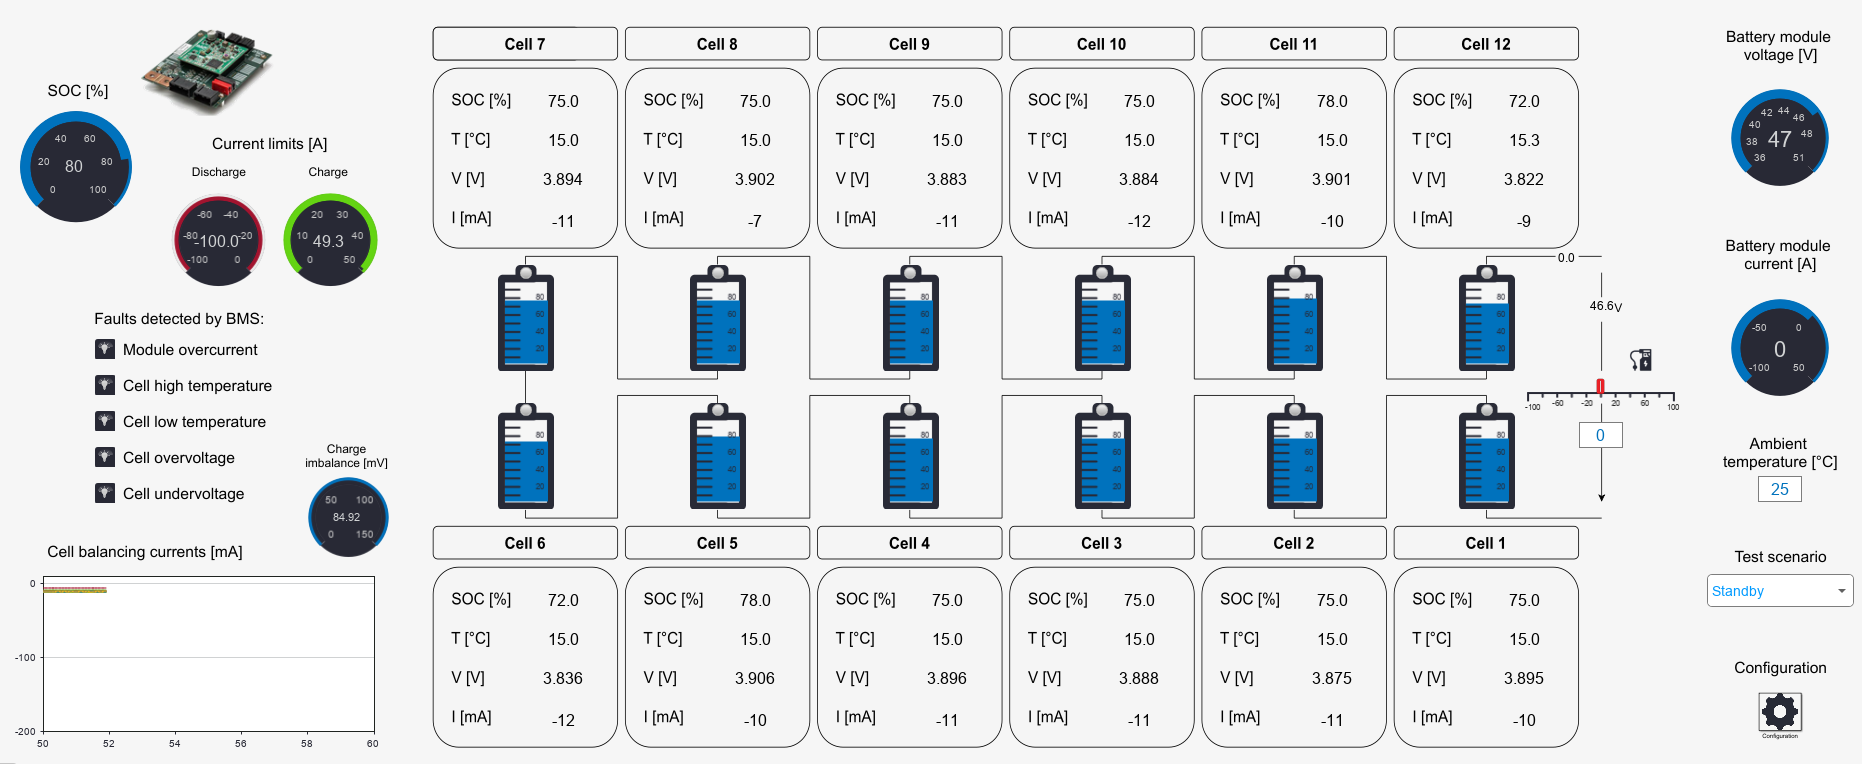

#### **A3. Trigger Passive Cell Balancing Process**

To trigger and validate the BMS passive cell balancing function, please follow the following steps:

- Navigate to the Test Scenario drop-down box and switch from Standby to Charging mode. Then, apply a charge current of 5A. This action results in an increase in the battery pack SOC and the SOC of individual battery cells.

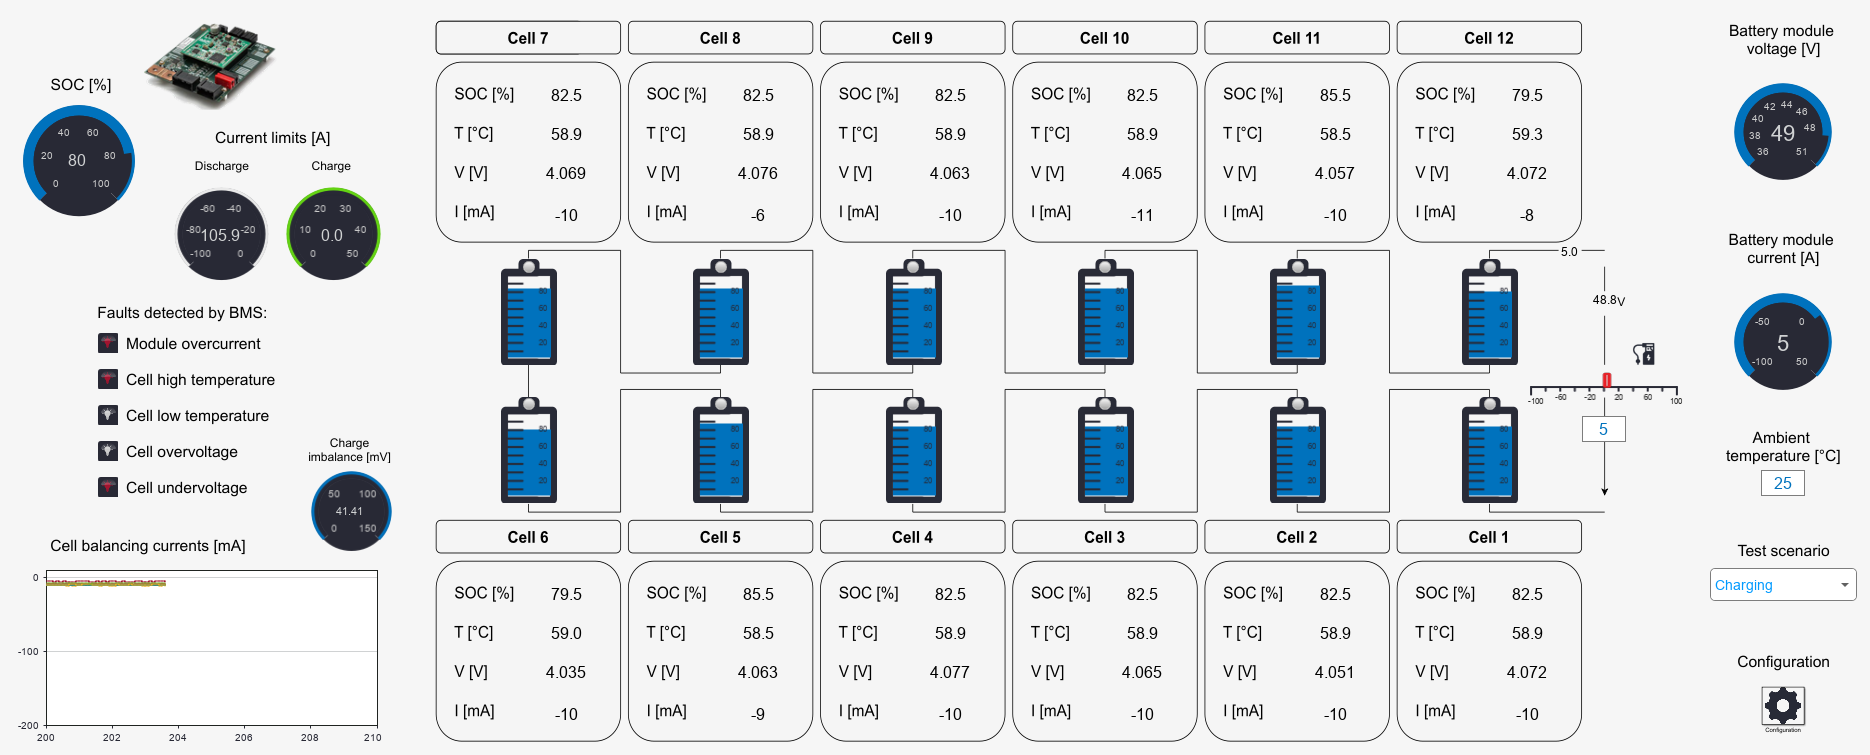

- Examine the BMS data. You will notice that the current charge imbalance among the 12 cells is approximately 40mV, but the BMS is configured to initiate cell balancing only if the imbalance exceeds 100mV.

- Click on the Configuration subsystem located at the bottom right corner of the User Interface subsystem and navigate to cell number 8. Change the voltage reference for this cell to 3 volts and enable override using the respective slider.

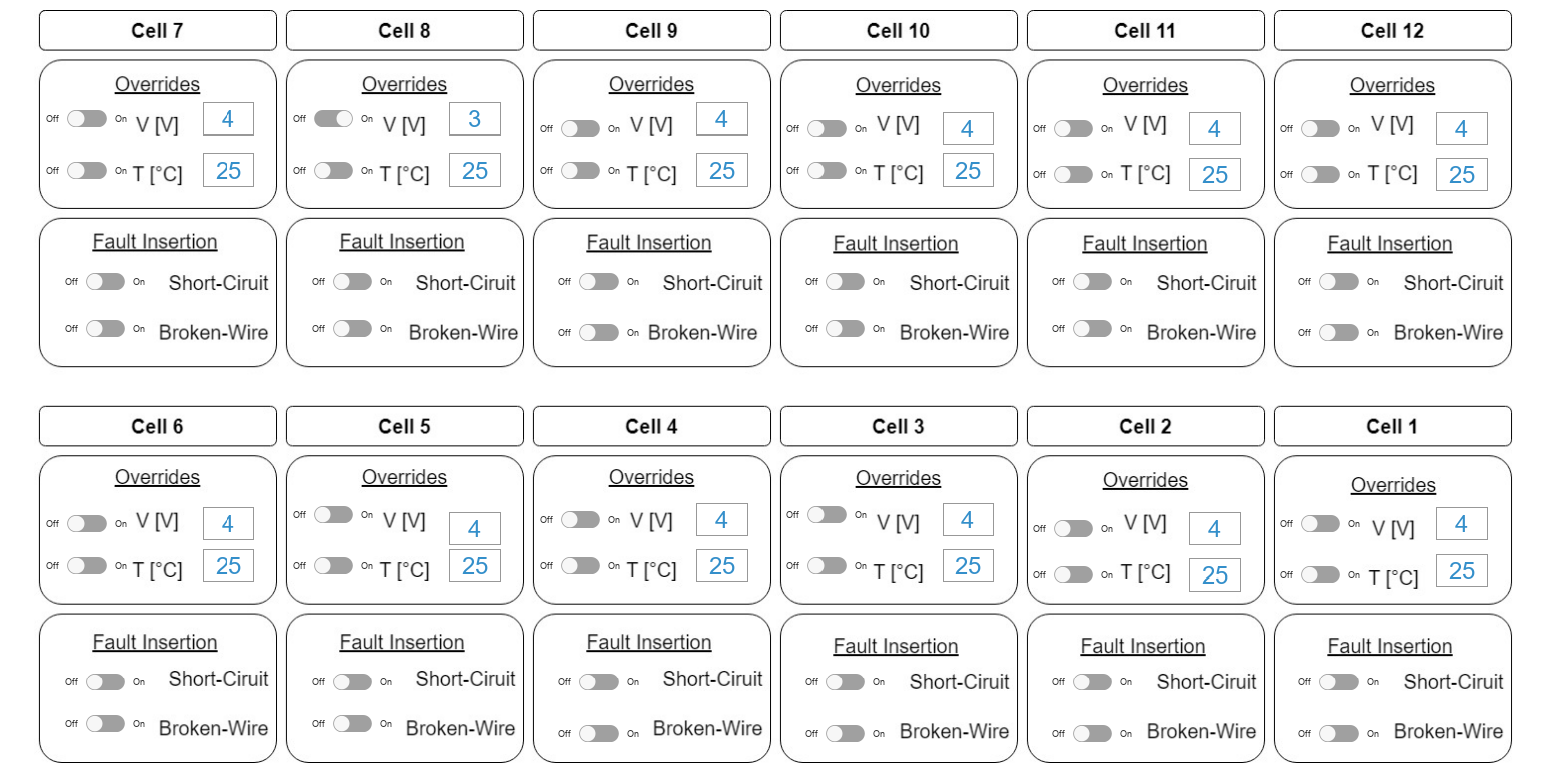

- As a result of this change, you will observe that cell number 8 has entered cell balancing mode with a discharge current of approximately 110mA in other cells that are being balanced.

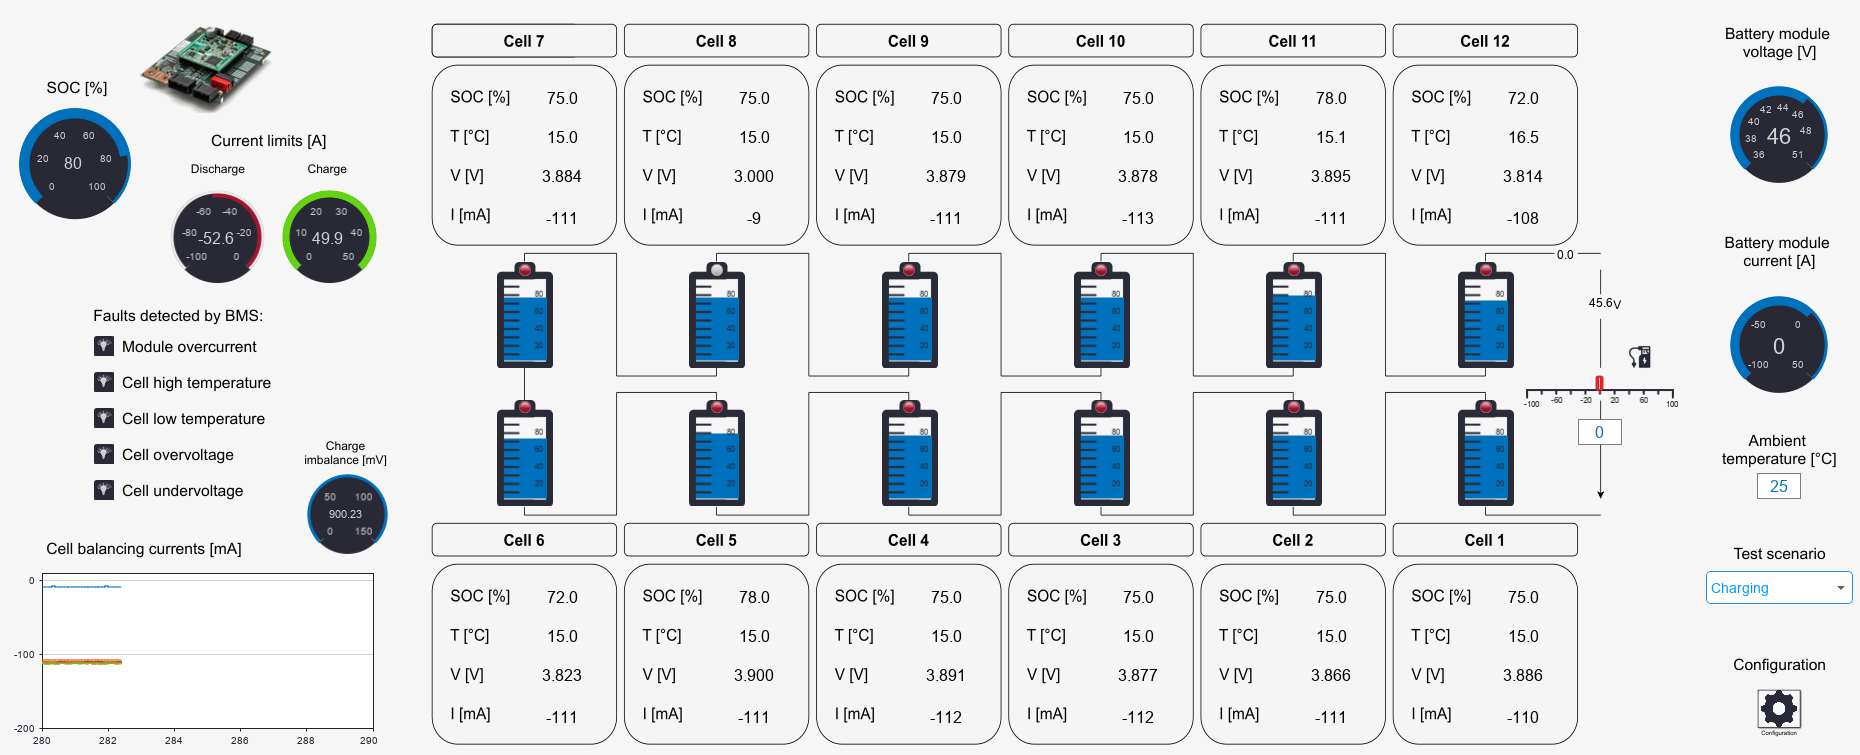

- All the cells have a higher discharge current as they balance out to reach the minimum voltage (3V in cell 8).

#### **A4. Perform Fault Insertion**

Navigate to the 'Test Scenario' drop-down box and switch from Charging to Driving mode and discharge the battery with 20 A. As anticipated, the BMS controller discontinues the cell balancing operation. You can also observe SOC and voltage of the battery cells decreasing, while the BMS calculates the discharge and charge current limits.

Given the current state of the batteries, the BMS permits a discharge current limit of approximately -50 A.

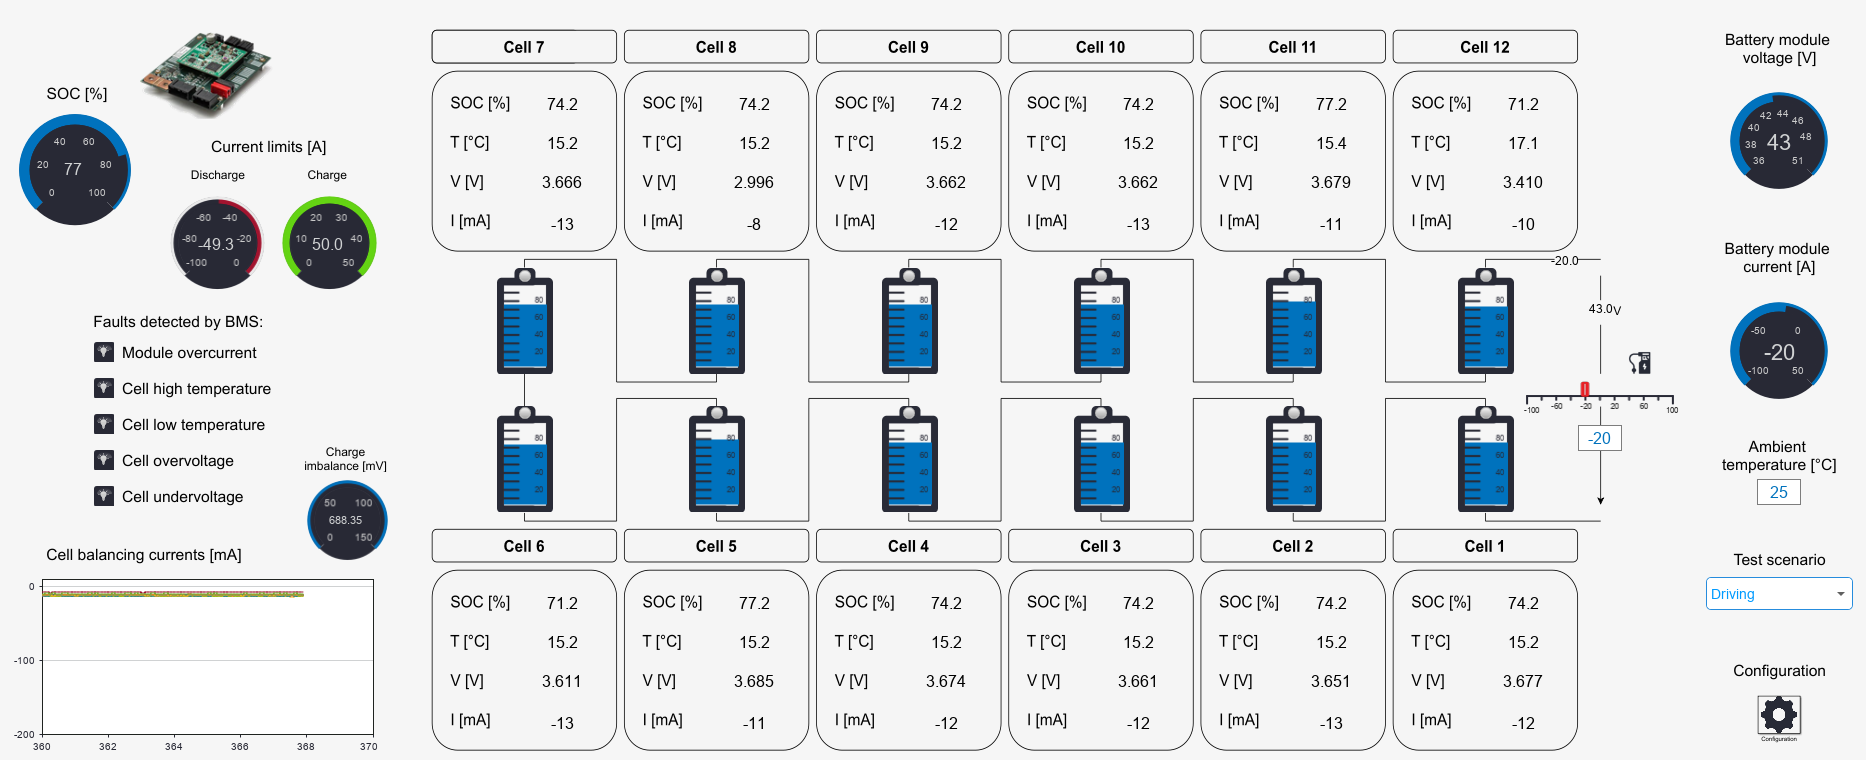

However, if we override this value with -120 A, the BMS immediately triggers an overcurrent fault.

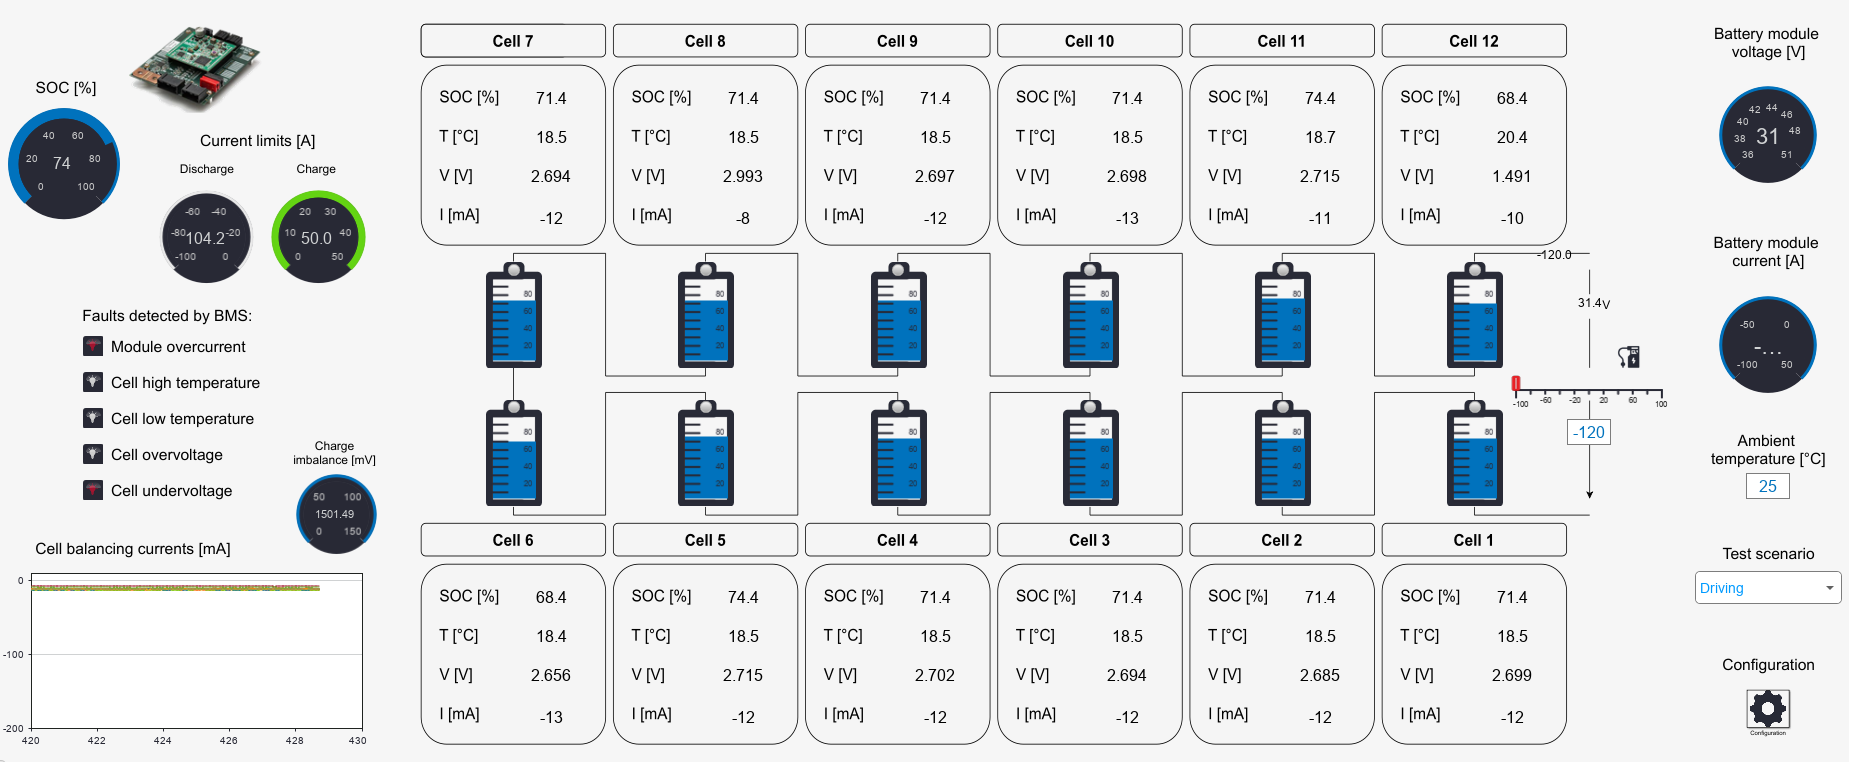

### B. BMS Interactive Testing using MATLAB® Interface App

The example includes a [MATLAB® App Designer](https://ch.mathworks.com/products/matlab/app-designer.html)'s app, which lets you perform BMS interactive testing without the need of [Simulink®](https://ch.mathworks.com/products/simulink.html).    

#### B1. Run the Interface App

% Open MATLAB interface app
BMSApp

The exercises mentioned in the previous section can also be practised using this interface app.

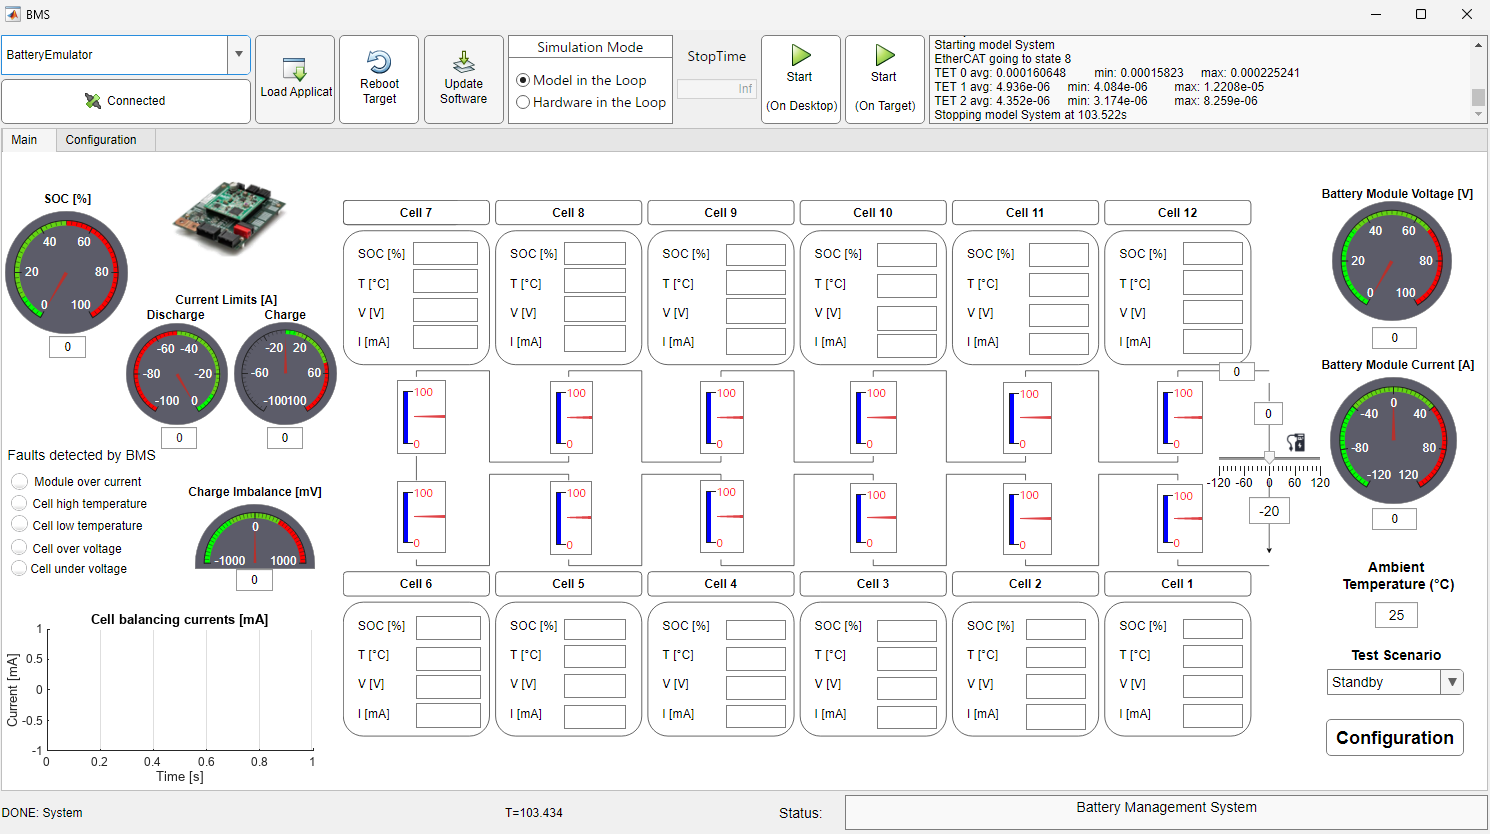

#### **B1. Examining Code View for Interface App**

% Open MATLAB interface app in Code View
edit BMSApp.mlapp

In App Designer, click the **Code View** tab to view the code that connects the real-time application to the [MATLAB®](https://ch.mathworks.com/products/matlab.html) interface app. 

### C. Automate BMS Testing

The following exercises shows how to further automate HIL testing of the BMS controller using [Simulink® Test™](https://ch.mathworks.com/products/simulink-test.html) and Continuous Integration (CI) workflow.

#### C1. Compare Test Results to Baseline Data   

This example shows how to create a simple test that compares test results to baseline data. Baseline tests are useful for regression testing when you change a model and want to ensure the output matches the baseline data.

Use the following commands to open [Simulink® Test™](https://ch.mathworks.com/products/simulink-test.html) Manager with a predefined HIL baseline test scenario.

sltestmgr
sltest.testmanager.load('BMS_HIL_Test.mldatx')
sltest.testmanager.run

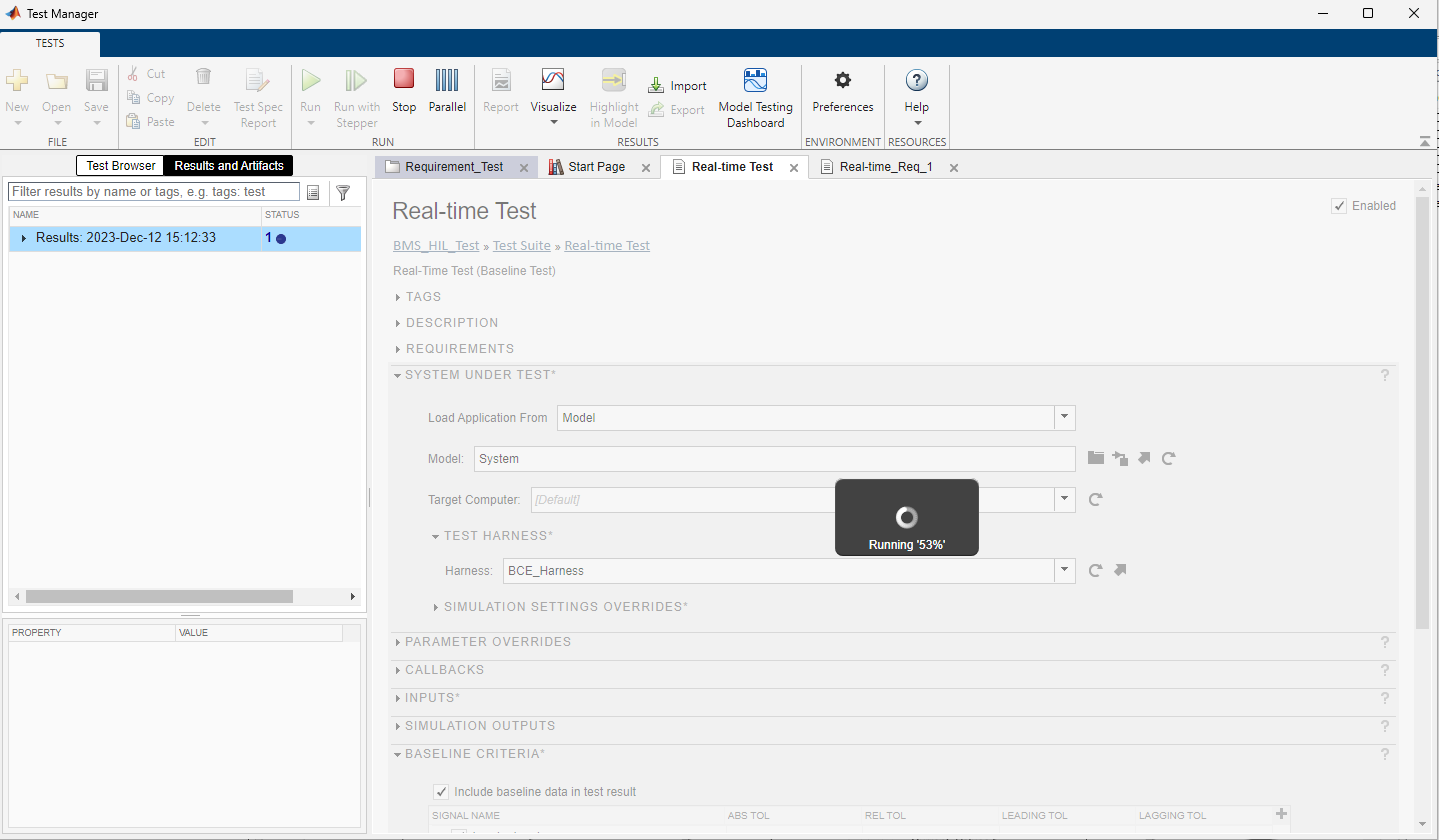

During the test run, the harness model ('BCE_HIL_Harness') is built, deployed, and run on the target machine. The created test harness is shown in the image below. 

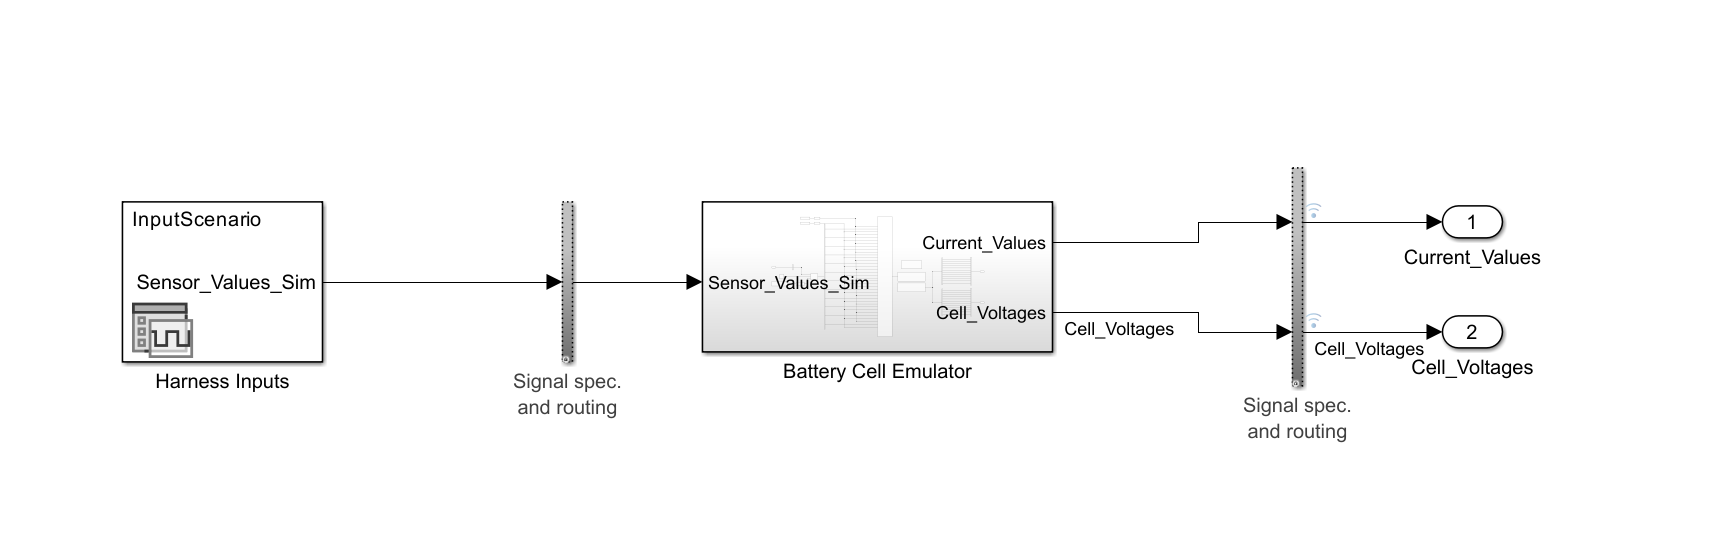

In the Results and Artifacts pane, expand the results and select any of the signals in the Baseline Criteria Result. The upper plot shows both the matching baseline and the new HIL simulation output data. The lower plot shows the difference between the two data sets for the entire run of 20s.

The tests also allow us to add a tolerance level as well as a delay value, which can be changed before every test depending on the accepted error margin.

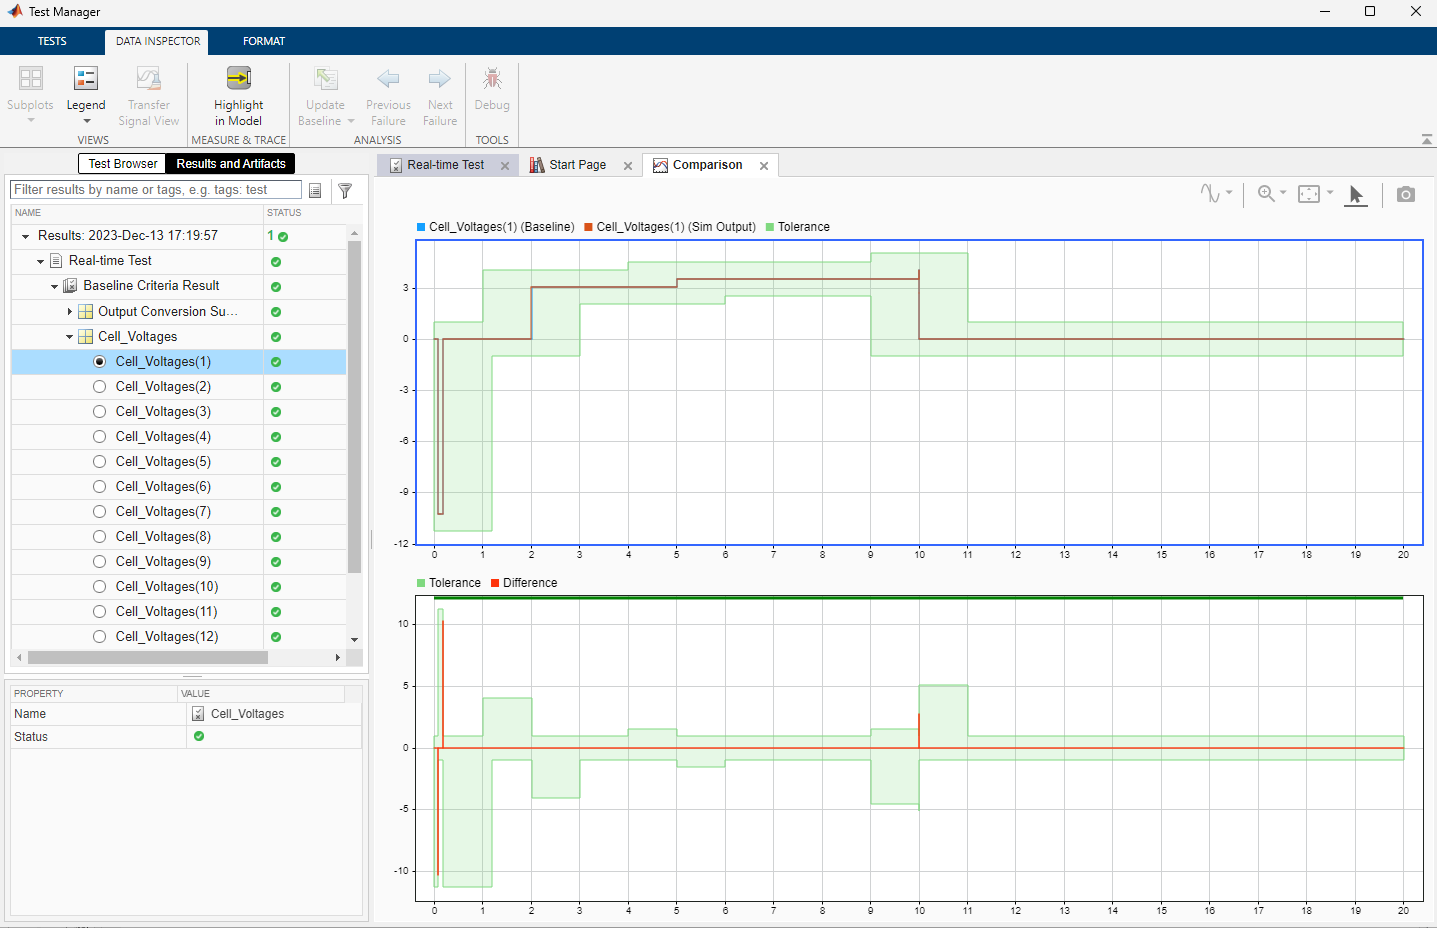

#### C2. Requirements-based Testing

This example shows some requirements defined in the application. These requirements are linked with MIL and HIL tests. The 'Implemented' and 'Verified' column in the image below shows if the requirements are implemented and the tests linked to each requirement have passed or not. These requirements are also linked to the sub-system/block in the model where the features are implemented. The requirements file is called 'Requirements.slreqx', saved under Tests folder.

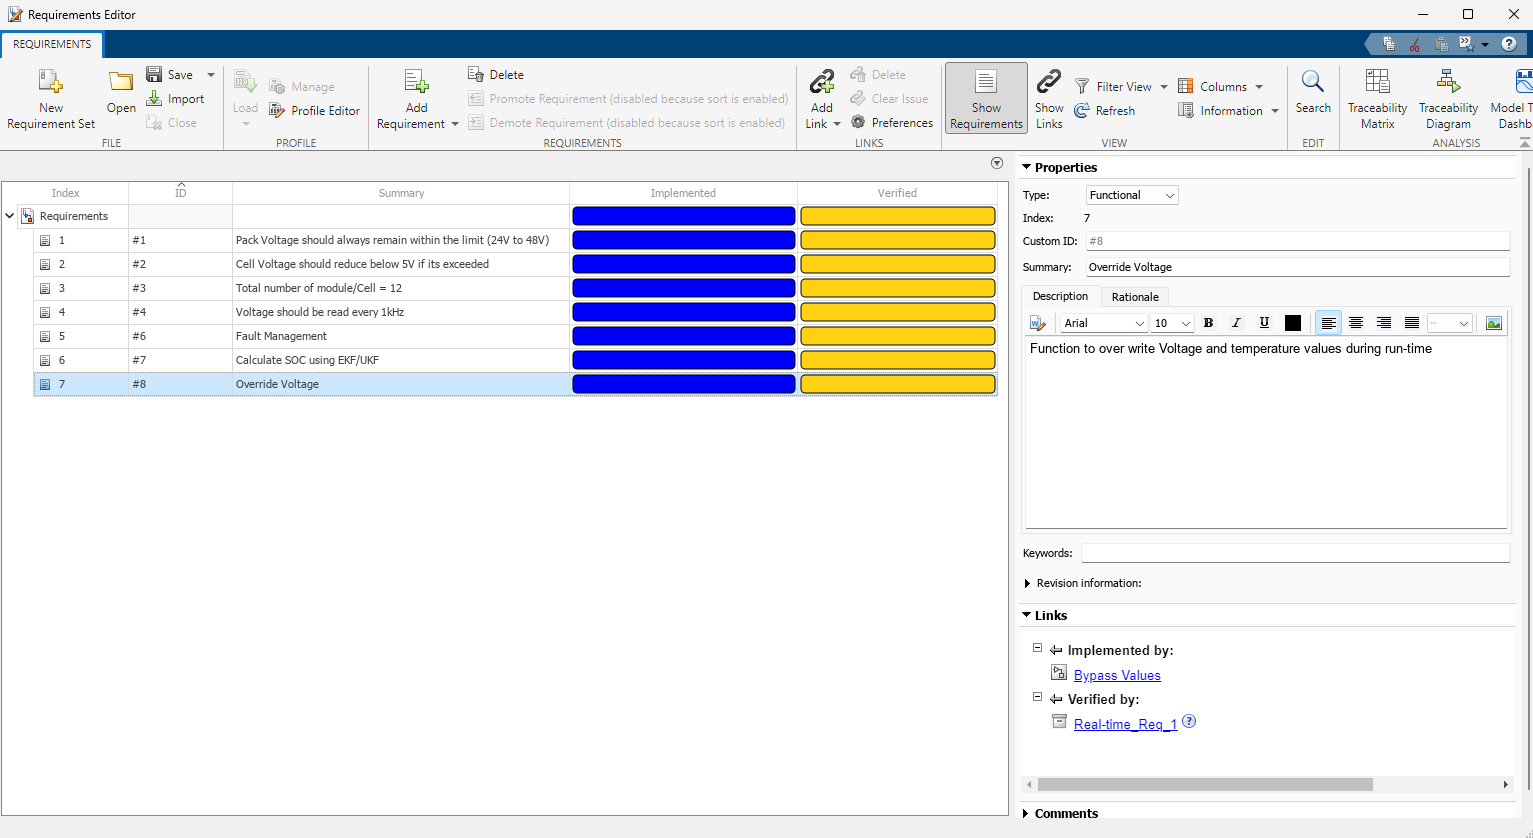

A simple requirement-based test is implemented and checks if a function that allows over-writing voltage and temperature values during real-time simulation run-time is implemented and verified. To do this, the function is triggered programmatically using Simulink Test™ callbacks and the voltage of the 12 Cells is forced to 2V.

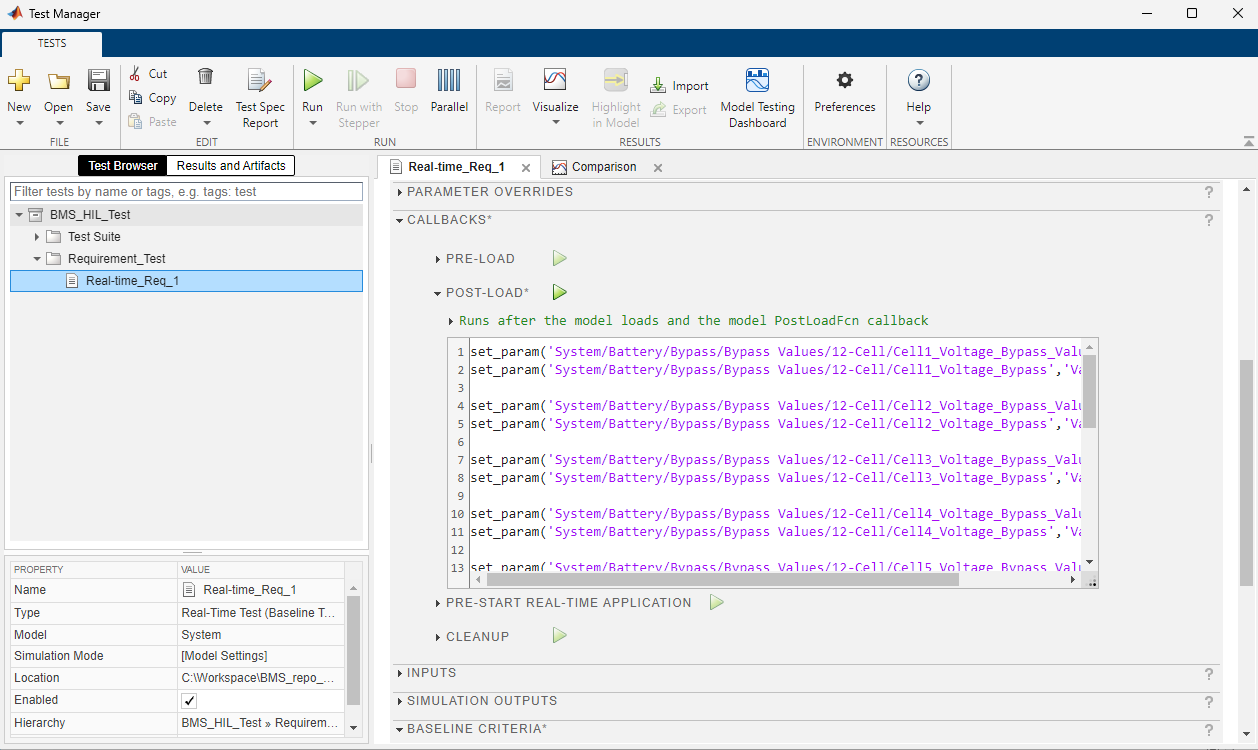

 This test runs the entire System model and captures the Battery Cell Emulator voltage readings. It also verifies that the voltages equal 2V for all Cells.

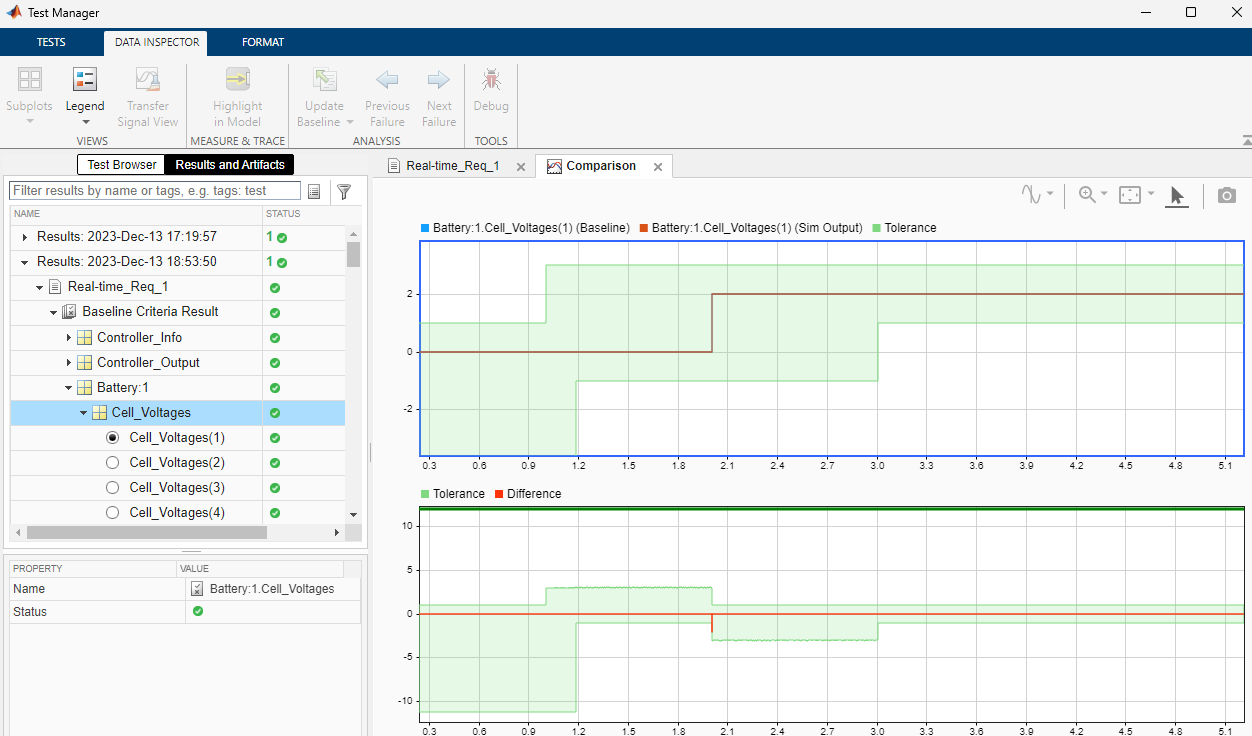

If the test passes, the Requirements Editor updates colour to green, indicating that the requirement is implemented and verified. Similarly, if all the tests pass, all the requirements in the Requirements Editor will turn green. To do this, run all the tests defined in 'BMS_HIL_Test.mldatx' and 'BMS_MIL_Test.mldatx' and check the Requirements Editor again.

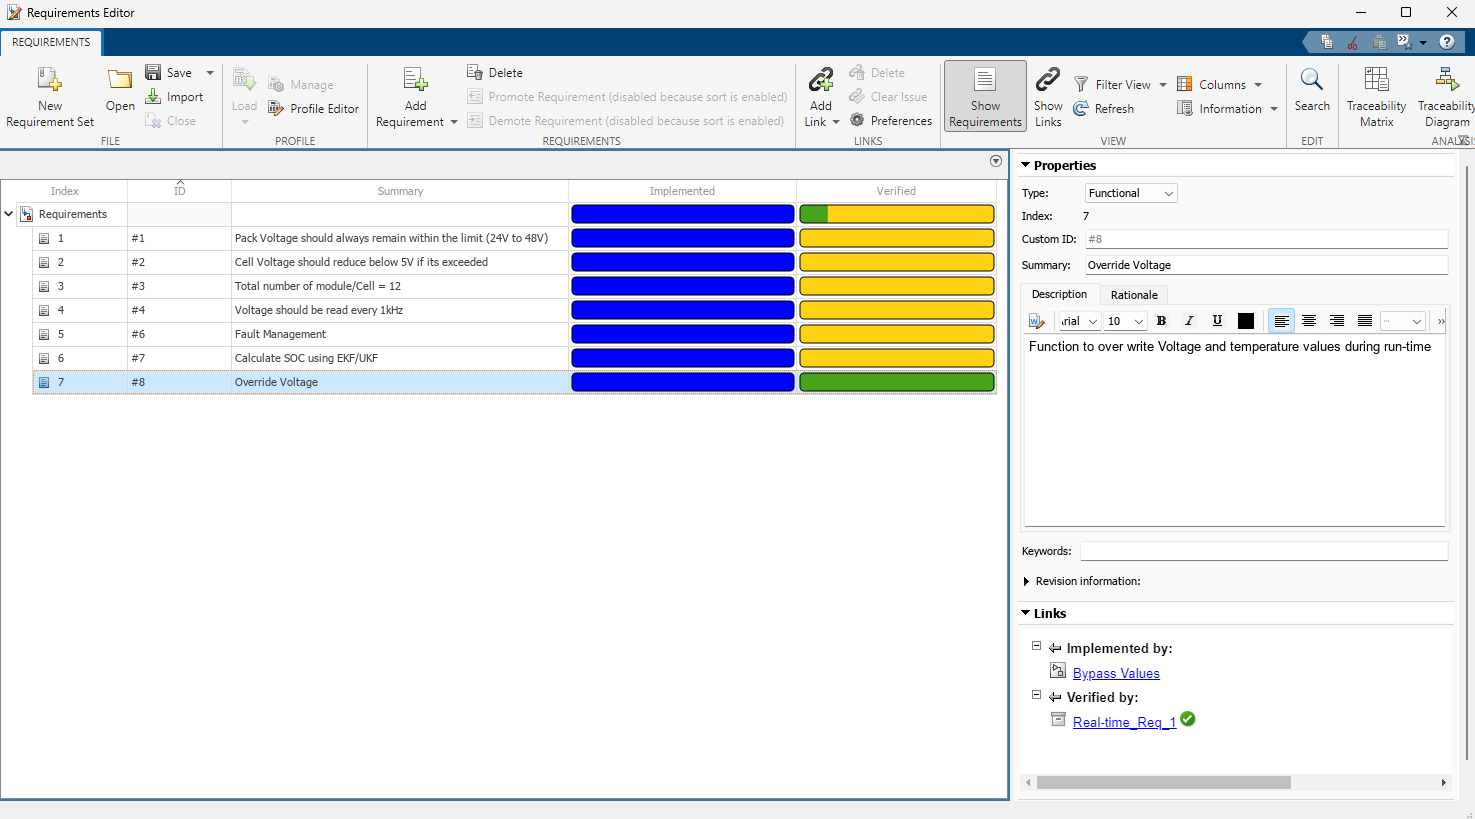

#### C3. Automate Testing with Continuous Integration

You can use Continuous Integration (CI) workflows to accelerate development and testing of your BMS controller. This enables your team to adopt and adhere to [agile development practices](https://ch.mathworks.com/solutions/agile-development.html) throughout your development lifecycle all without losing the benefits of HIL simulation and testing.

You can run [MATLAB®](https://ch.mathworks.com/products/matlab.html), [Simulink®](https://ch.mathworks.com/products/simulink.html), [Simulink® Real-Time™](https://ch.mathworks.com/products/simulink-real-time.html) and [Simulink® Test™](https://ch.mathworks.com/products/simulink-test.html) on a on-premises HIL CI server and benefit from off-the-shelf integration with mainstay CI platforms like Jenkins, Gitlab or Azure Devops. And all can be orchestrated to work with hardware and complement your HIL testing workflows.

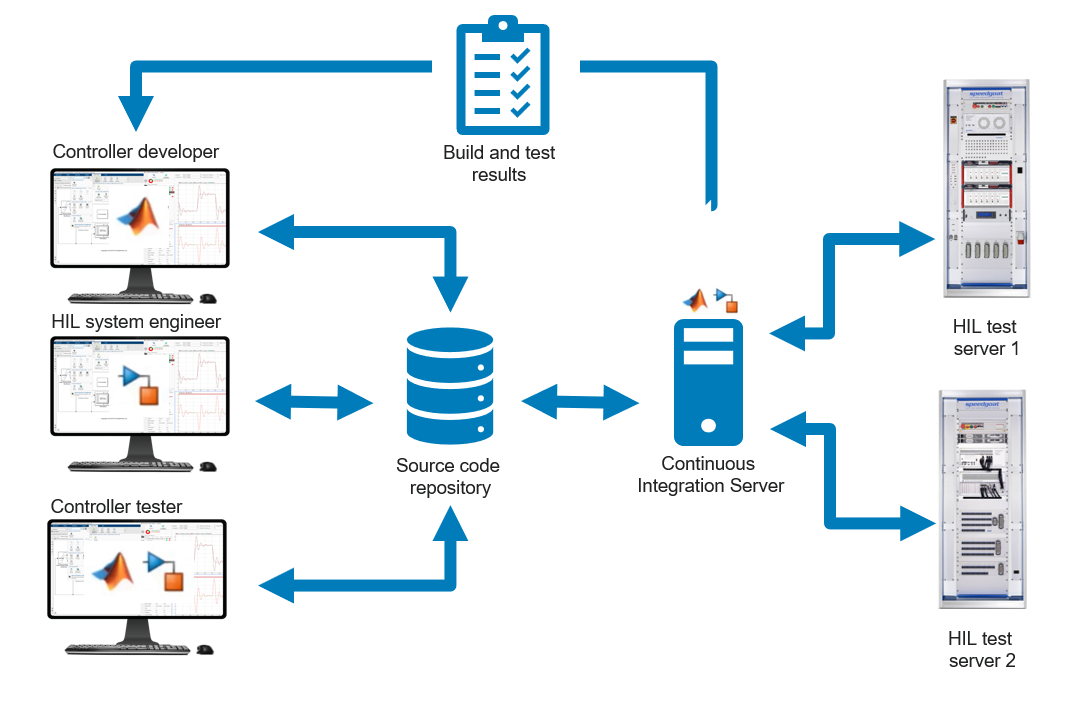

The following command executes an example CI pipeline on that carries out the following actions:

run CI_HIL_test.m

The following steps are take place when the above command is executed.

- Opens the BMS-Controller-HIL [Simulink®](https://ch.mathworks.com/products/simulink.html) project.

- Loads the test file 'BMS_HIL_Test.mldatx' in the Simulink Test Manager.

- Runs [Simulink® Test™](https://ch.mathworks.com/products/simulink-test.html) test-cases defined within the file.

- Generates a .zip file with the test results.

Next, you have the option to integrate this and other CI pipelines into a CI platform, allowing for the complete automation of tasks such as downloading the [Simulink®](https://ch.mathworks.com/products/simulink.html) project, executing HIL test cases, and automatically sending notifications in the event of a testing pipeline failure. 

For a comprehensive demonstration of CI within the context of controller HIL testing, we recommend watching the following webinar: [Automated and Continuous Hardware-in-the-Loop Testing](https://www.speedgoat.com/knowledge-center/webinars/automated-and-continuous-hardware-in-the-loop-testing)

## Release Notes

open README.md